# `Exp-04: Maclaurin Series and Partial Functions`

## `Table of Contents:`

- Maclaurin's series

- Exercise

- Partial Derivatives

- Example

#### Maclaurin's series

syms x
f=sqrt(1+sin(2*x))

$$f = \sqrt{\sin\left(2\,x\right)+1}$$

M_1=taylor(f,x,0,'order',10)

$$M\_1 = \frac{x^{9}}{362880}+\frac{x^{8}}{40320}-\frac{x^{7}}{5040}-\frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}-\frac{x^{3}}{6}-\frac{x^{2}}{2}+x+1$$

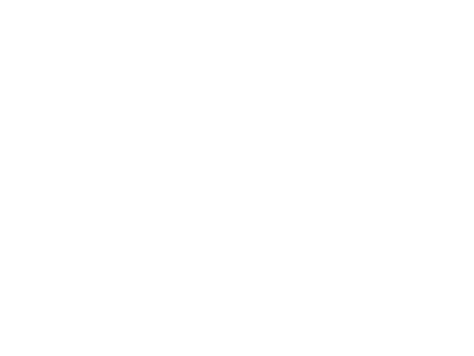

fplot(f)
hold on
fplot(M_1)
hold off

#### Exercise

%Obtain Maclaurin series expansion of g(x)=e^x upto the term x^6 and store it as h. Also obtain the graph.
syms x
g1(x)=exp(x)

$$g1(x) = {\mathrm{e}}^{x}$$

h=taylor(g1(x),x,0,'order',7)

$$h = \frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

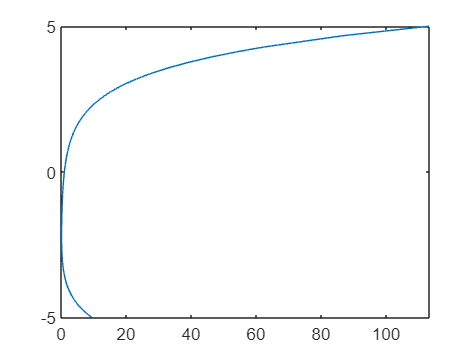

fplot(h,x)

%Obtain the Maclaurin series of g(x)=cosx and plot the graph.
g2(x)=cos(x)

$$g2(x) = \cos\left(x\right)$$

P=taylor(g2,x,0)

$$P(x) = \frac{x^{4}}{24}-\frac{x^{2}}{2}+1$$

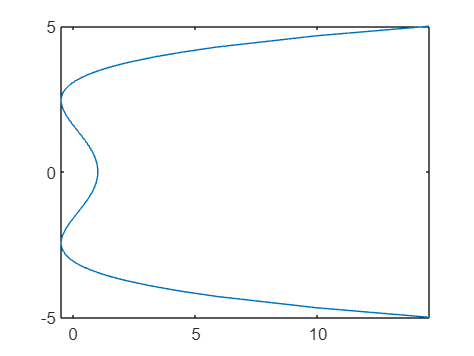

fplot(P,x)

%Obtain the Maclaurin series of g(x)=sinx and plot the graph
g3(x)=sin(x)

$$g3(x) = \sin\left(x\right)$$

r=taylor(g3,x,0)

$$r(x) = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

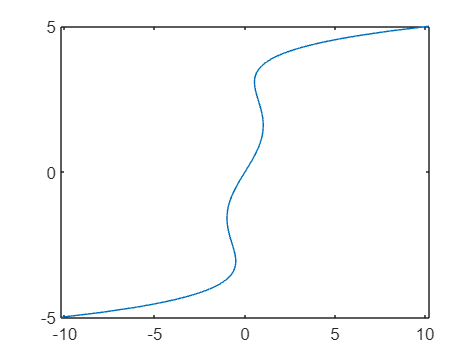

fplot(r,x)

#### Partial Derivatives

clear
syms x y
z=x^3+y^3+3*x*y

$$z = x^{3}+3\,x\,y+y^{3}$$

z_x=diff(z,x) %y is constant

$$z\_x = 3\,x^{2}+3\,y$$

z_y=diff(z,y) %x is constant

$$z\_y = 3\,y^{2}+3\,x$$

z_xx=diff(z,x,2) %second order derivative w.r.t x

$$z\_xx = 6\,x$$

z_yy=diff(z,y,2) %second order derivative w.r.t y

$$z\_yy = 6\,y$$

z_xy=diff(z_x,y) %mixed derivative

$$z\_xy = 3$$

#### Example

clear
%Find the partial derivative of u=(x^2+y^2)/x+y.1st order and 2nd order derivative and show that mixed derivative are equal.
syms x y u
u=(x^2+y^2)/(x+y)

$$u = \frac{x^{2}+y^{2}}{x+y}$$

u_x=diff(u,x)

$$u\_x = \frac{2\,x}{x+y}-\frac{x^{2}+y^{2}}{{\left(x+y\right)}^{2}}$$

u_y=diff(u,y)

$$u\_y = \frac{2\,y}{x+y}-\frac{x^{2}+y^{2}}{{\left(x+y\right)}^{2}}$$

u_xy=diff(u_x,y,2)

$$u\_xy = \frac{4\,x}{{\left(x+y\right)}^{3}}-\frac{6\,\left(x^{2}+y^{2}\right)}{{\left(x+y\right)}^{4}}+\frac{8\,y}{{\left(x+y\right)}^{3}}-\frac{2}{{\left(x+y\right)}^{2}}$$

u_yx=diff(u_y,x,2)

$$u\_yx = \frac{8\,x}{{\left(x+y\right)}^{3}}-\frac{6\,\left(x^{2}+y^{2}\right)}{{\left(x+y\right)}^{4}}+\frac{4\,y}{{\left(x+y\right)}^{3}}-\frac{2}{{\left(x+y\right)}^{2}}$$

%u_xy=u_yx